%%y = [1000,1000,1000,1500,2000,2000,2000,1500,1000]/1000;
%%x = [1000,3000,5000,5000,5000,3000,1000,1000,1000]/1000;
x = [1400,1800,2200,2600,3000,3400,3400,3800,3800,4200,4200,4600,5000,5000]/1000;
y = [1000,1000,1000,1000,1000,1000,1400,1400,1800,1800,2200,2200,2200,2600]/1000;
x_wpl = [x(1)];
y_wpl = [y(1)];
for i=2:length(x)-1
    phi1 = atan2(y(i)-y(i-1),x(i)-x(i-1));
    phi2 = atan2(y(i+1)-y(i),x(i+1)-x(i));
    if phi1 ~= phi2
        x_wpl = [x_wpl, x(i)];
        y_wpl = [y_wpl, y(i)];
    end
end
x_wpl = [x_wpl, x(length(x))]

x_wpl =     1.4000    3.4000    3.4000    3.8000    3.8000    4.2000    4.2000    5.0000    5.0000


y_wpl = [y_wpl, y(length(y))]

y_wpl =     1.0000    1.0000    1.4000    1.4000    1.8000    1.8000    2.2000    2.2000    2.6000


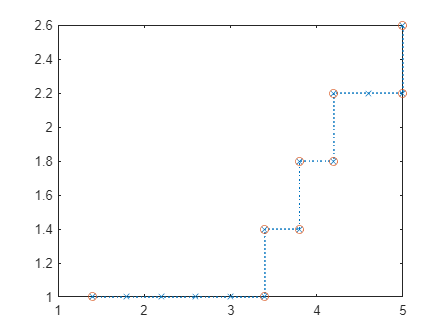


figure()
plot(x,y, "x:");
hold on;
plot(x_wpl, y_wpl, "o")


path = Path(x,y,0.2);

x =     1.4000    3.4000    3.4000    3.8000    3.8000    4.2000    4.2000    5.0000    5.0000


y =     1.0000    1.0000    1.4000    1.4000    1.8000    1.8000    2.2000    2.2000    2.6000


len = path.length

len = 4.6725

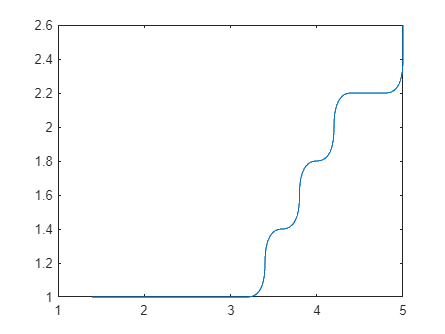

s = [0:0.01:len];
[x,y, phi] = path.getPoint(s);
[x1,y1, phi1] = path.diff(s);
[x2,y2, phi2] = path.diff(s,2);
%[kx, ky] = path.getMaxSegmentCurvature(s)


figure();
plot(x,y)

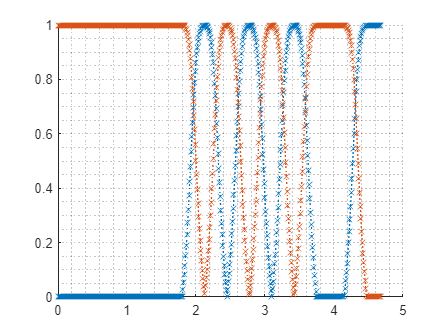

figure();
%plot(s,x1, ":x");
hold on
%plot(s,y1, ":x");
plot(s, abs(y1),":x")
plot(s, abs(x1),":x")
grid minor


%figure()
%plot(s, atan2d(y1,x1))


planner = TrajectoryPlannerSimple(path, 0.5,0.7,100,100);
planner = planner.generateTrajectory(0.05);

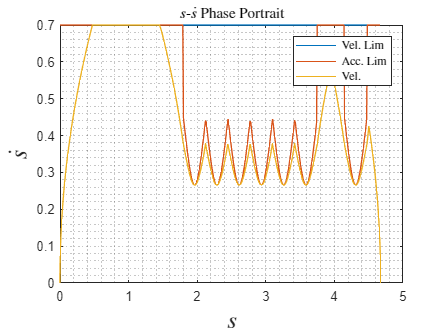

figure()
planner.plotVelLimPhasePlane(true)

[x, y]  = path.getPoint(planner.pos)

x =     1.4000
    1.4000
    1.4012
    1.4037
    1.4075
    1.4125
    1.4187
    1.4263
    1.4350
    1.4450


y =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


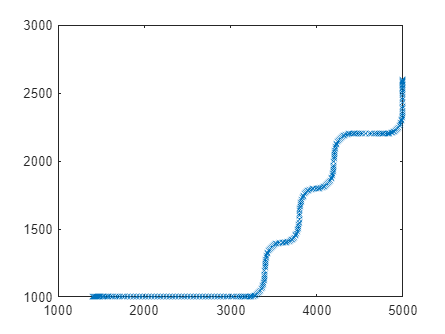

[dx,dy] = path.diff(planner.pos);
x = x*1000;
y = y*1000;

figure();
plot(x, y, ":x");

dataPath = "E:\hawino\Measurements\Trajectory\realTrajectory.csv"

dataPath = "E:\hawino\Measurements\Trajectory\realTrajectory.csv"

data = readtable(dataPath)

data = 1355×10 table
    Name     x_YX      x_YY     xRef_YRefX    xRef_YRefY    xObs_YObsX    xObs_YObsY    vYworldToSimulink    vXworldToSimulink      e   
    ____    ______    ______    __________    __________    __________    __________    _________________    _________________    ______

    NaN         10        10        10            10              10            10              10                   10               10
    NaN        NaN       NaN       NaN           NaN             NaN           NaN             NaN                  NaN              NaN
    NaN        NaN       NaN       NaN           NaN             NaN           NaN        


vx = table2array(data(:,"vXworldToSimulink"))/1000

vx =     0.0494
    0.0336
    0.0061
    0.0012
    0.0114
   -0.0083
   -0.0103
    0.0277
    0.0303
   -0.0098


vy = table2array(data(:,"vYworldToSimulink"))/1000

vy =     0.0270
    0.0397
    0.0475
    0.0184
    0.0267
    0.0136
   -0.0094
    0.0335
    0.0269
   -0.0219


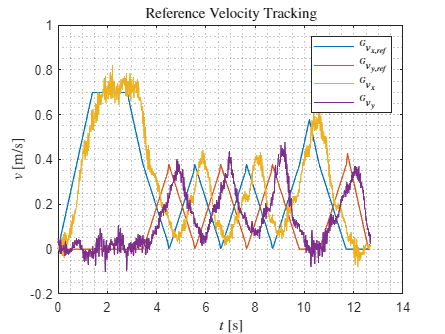


figure();
t     = [0:length(planner.pos)-1]*0.05;
tmeas = [0:5*length(t)-1]*0.01;
plot(t,dx.*planner.vel);
hold on;
grid minor;
plot(t,dy.*planner.vel);
plot(tmeas,vx(1:length(tmeas)));
plot(tmeas,vy(1:length(tmeas)));

title("Reference Velocity Tracking","interpreter","latex")
xlabel("$t$ [s]","interpreter","latex")
ylabel("$v$ [m/s]","interpreter","latex")

legend(["$^Gv_{x,ref}$","$^Gv_{y,ref}$","$^Gv_x$","$^Gv_y$"],"interpreter","latex")

#### **Switching Points**

%VII. A. 1) Caused by Acceleration Constraints and Discontinuous
s = [0:0.001:path.length] 
tol = 0.04;
idx = find((abs(diff(velMaxAcc)) > tol) == 1, 1,"first")
sp = s(idx+2);
sm = s(idx);

[~, dvelMaxP, velMaxAccP]     = planner.velMax([s(idx+1), sp])
[~, dvelMaxM, velMacAccM]     = planner.velMax([sm ,s(idx+1)])
[~, accMaxP]                  = planner.accLim(sp, velMaxAccP)
[~, accMaxM]                  = planner.accLim(sm, velMacAccM)

dvelMaxAccP = diff(velMaxAccP)./diff([s(idx+1), sp])
dvelMacAccM = diff(velMacAccM)./diff([sm ,s(idx+1)])

velMaxAccP = velMaxAccP(2);
velMacAccM = velMacAccM(1);

foundSwitchingPoint = ((velMacAccM < velMaxAccP) & (accMaxM >= dvelMacAccM)) | ((velMacAccM > velMaxAccP) & (accMaxP <= dvelMaxAccP))
ssw = s(idx+1)

%VII. A. 2) Caused by Acceleration Constraints and Continuous and Nondifferentiable

idxY = find(diff(sign(dfy(s, path))) ~= 0, 1, "first") 
idxX = find(diff(sign(dfx(s, path))) ~= 0, 1, "first") 

if ~isempty(idxY) 
    sy = fzero(@(s)dfy(s,path), [s(idxY-10) s(idxY+10)])
    foundSwitchingPoint = length(sy) ~= 0
end

if length(idxX) ~= 0
    sx = fzero(@(s)dfx(s,path), [s(idxX-10) s(idxX+10)])
    foundSwitchingPoint = length(sx) ~= 0
end


%VII. A. 2) B. Caused by Velocity Constraints and Continuous
% idx = find(diff(sign(swPointContVel(s,planner))) ~= 0) 
% s(idx+1)
% foundSwitchingPoint = length(s(idx+1)) ~= 0
figure()


%VII. A. 2) B. Caused by Velocity Constraints and Discontinuous
[ddx, ddy] = path.diff(s, 2);
tol = 0.3;
idx = find((abs(diff(ddx)) > tol) == 1, 1,"first")

[velMaxM, ~, velMaxAccM]         = planner.velMax([s(idx) s(idx+1)]);
[velMaxP, ~, velMacAccP]         = planner.velMax([s(idx+1) s(idx+2)]);
[accMinM, ~]                     = planner.accLim(s(idx+1), velMaxM);
[accMinP, ~]                     = planner.accLim(s(idx+1), velMaxP);

foundSwitchingPoint = (accMinM >= diff(velMaxAccM)) & (accMinP <= diff(velMacAccP))

idx = find((abs(diff(ddy)) > tol) == 1, 1,"first")
[velMaxM, ~, velMaxAccM]         = planner.velMax([s(idx) s(idx+1)]);
[velMaxP, ~, velMacAccP]         = planner.velMax([s(idx+1) s(idx+2)]);
[accMinM, ~]                     = planner.accLim(s(idx+1), velMaxM);
[accMinP, ~]                     = planner.accLim(s(idx+1), velMaxP);

foundSwitchingPoint = (accMinM >= diff(velMaxAccM)) & (accMinP <= diff(velMacAccP))


## Backward Integration crossing point search

x1 = [[0:0.01:4],zeros(1,1000) ]

x1 =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


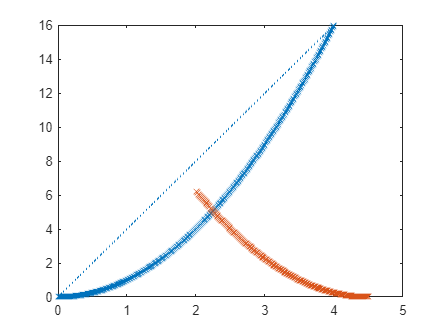

y1 = x1.^2;

x2 =[4.5:-0.0133:2];
y2 = (x2-4.5).^2;

figure();
plot(x1, y1,":x")
hold on
plot(x2, y2,":x")


for i = 1:length(x2)
    idx1 = find(x2(i) < x1, 1, "first");
    if(y2(i) > y1(idx1))
        idx2 = i;
        break;
    end
end
length(y1)

ans = 1401

x1(idx1:idx1+idx2-2) = flip(x2(1:idx2-1))

x1 =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


y1(idx1:idx1+idx2-2) = flip(y2(1:idx2-1))

y1 =          0    0.0001    0.0004    0.0009    0.0016    0.0025    0.0036    0.0049    0.0064    0.0081    0.0100    0.0121    0.0144    0.0169    0.0196    0.0225    0.0256    0.0289    0.0324    0.0361    0.0400    0.0441    0.0484    0.0529    0.0576    0.0625    0.0676    0.0729    0.0784    0.0841    0.0900    0.0961    0.1024    0.1089    0.1156    0.1225    0.1296    0.1369    0.1444    0.1521    0.1600    0.1681    0.1764    0.1849    0.1936    0.2025    0.2116    0.2209    0.2304    0.2401


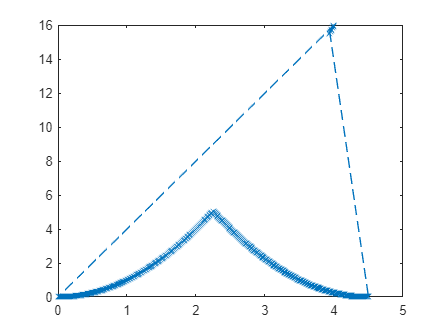

figure()
plot(x1,y1,"--x")

x = [1000, 3000, 3000]

x =         1000        3000        3000


y = [1000, 1000, 3000]

y =         1000        1000        3000


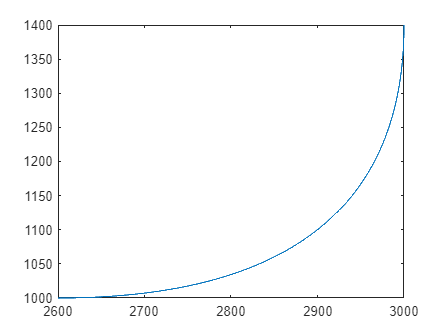


b = BezierCurve(x,y, 400);
s = [0:0.1:b.length];
[x,y] = b.getPoint(s);
figure();
plot(x,y);


p = 0;
b.getPoint(p)

ans = 2600

function swPointContVel = swPointContVel(s, planner)
        [valMax, ~, velMaxAcc] = planner.velMax(s);
        [accMin, ~]  = planner.accLim(s, valMax);
        dvelMaxAcc  =diff([0; velMaxAcc]);
        swPointContVel  = accMin -dvelMaxAcc;       
end

function ret = dvelMaxAccFunc(s, planner)
      ds  = 1e-6;
     [~, ~, velMaxAcc] = planner.velMax([s-ds, s+ds]);
     ret = diff(velMaxAcc)/(2*ds);
end


